# ME 552 Final

Dominic Riccoboni

Date Created: 12/6/2021

clear all

## Constants

sigma = 5.67037e-8;%[W/m^2/K^4] Stephan-Boltzmann constant
h = .3; %Height of cylinder [m]
r = 0.08; %Radius of cylinder [m]
T1 = 1300; %Temperature at surface 1, the bottom of the cylinder [K]
T2 = 400; %Temperature at surface 2, the top of the cylinder [K]
Ts = 1000; %Temperature of each surface area other than 1 and 2 [K]
Ns = [2, 4:4:20]; %Vector containing the number of surfaces used in the enclosure analysis. Each of these will be a separate instance of the analysis.
A = pi*r^2; %Area of the top and bottom disks
eps = 0.8; %Epsilon, the emissivity of the gray-diffuse surfaces assumption

## Configuration Factors

Create a 5x1 cell array for the final configuration factor matrices. 

F = cell(length(Ns),1); %Cell array for final configuration factors

Also, create a cell array for intermediate view factor calculations given by:


$$F_{1-dk}~= ~F_{dk-1} ~= ~\frac{1}{2}(X_k - \sqrt{X_k^2 - 4})$$


Where:


$$X_k ~= ~2 + \frac{1}{R_k^2}, ~~R_k ~=~ \frac{r}{k\Delta h}$$


F_1_dk = cell(length(Ns),1); %Cell array for intermediate configuration factor calculations

For pre-allocation, fill F with NaN arrays of size $ N= N_s+2$ and F_1_dk with NaN vectors of length $N_s$ for $N_s = 4,8,12,16,20$:

for n = 1:length(Ns)
    
    N = Ns(n) + 2; %Top and bottom surface must be added to get total number of surfaces

    F{n} = NaN(N); %NxN matrix of view factors (N^2 total)
    F_1_dk{n} = NaN(Ns(n),1); %Ns number of intermediate disks - View factors from bottom disk to that disk

end



Compute $F_{1-2}$ and $F_{2-1}$:


$$F_{1-2}~= ~F_{2-1} ~= ~\frac{1}{2}(X - \sqrt{X^2 - 4})$$


Where


$$X ~= ~2 + \frac{1}{R^2}, ~~R ~=~ \frac{r}{h}$$


R = r/h; 
X = 2 + 1/R^2;
F12 = .5*(X - sqrt(X^2 - 4));

Compute the configuration factors for each value of $N_s$:

for n = 1:length(Ns) %For each Ns value, compute all the configuration factors and fill the relevant cell array elements

    N = Ns(n) + 2; %Total number of surfaces for this Ns value

    %Compute top bottom and bottom top view factors
    F{n}(1,2) = F12; %View factor for 1-2 computed above is placed in the relevant position
    F{n}(2,1) = F12; %The equivalent factor for 2-1 is placed as well

    %Bottom and top self-view factors are zero
    F{n}(1,1) = 0;
    F{n}(2,2) = 0;
 
    %Compute intermediate view factors for dk = 1:(Ns - 1)
    dh = h/Ns(n); %Delta h for each disk
    Rk = r/dh./(1:(Ns(n)-1)); %Create a vector of Rk values from 1 to Ns-1
    Xk = 2 + 1./Rk.^2; %Create a vecotor of Xk values from 1 to Ns-1
    F_1_dk{n}(1:(Ns(n)-1)) = .5*(Xk - sqrt(Xk.^2 - 4));%Compute the intermediate disk view factors

    %Intermediate view factor for dk = Ns is F_1_2
    F_1_dk{n}(end) = F12;
    
    %F_1_3 and F_2_N are not given by inner loop 1 below and must be specified here
    F{n}(1,3) = 1 - F_1_dk{n}(1); 
    F{n}(2,N) = F{n}(1,3);

    %% Inner Loop 1
    %Get view factors from surfaces 1 and 2 to surfaces 3 to Ns. 
    for k = 1:(Ns(n)-1)
        
        %From summation and by symmetry:
        F{n}(1,k+3) = F_1_dk{n}(k) - F_1_dk{n}(k+1); 
        F{n}(2,N-k) = F{n}(1,k+3);
    end

    %%Inner Loop 2 
    %Use reciprocity to get the view factors from surfaces 3 to N to
    %surfaces 1 and 2. Also compute the view factor for each of these surfaces to itself.
    %Each of the subdivisions can see itself and via symmetry, this view
    %factor is shared by all
    for k = 3:N
        
        %From reciprocity:
        Ak = 2*pi*r*dh; % kth area
        F{n}(k,1) = A/Ak*F{n}(1,k); 
        F{n}(k,2) = A/Ak*F{n}(2,k); 
        
        %Each sees itself the same amount:
        F{n}(k,k) = 1 - 2*F{n}(3,1);
    end


    %%Inner Loop 3 contains two indices and consequently two for loops
    for j = 1:(Ns(n)-1)
        for k = 3:(N-j)
            
        %For two sides adjacent to one another, the view factor is the same and given by:
        F{n}(k, k+j) =  F{n}(j+2, 1) - F{n}(j+3, 1);
        F{n}(k+j, k) = F{n}(k, k+j);

        end
    end


end


## Compute the Heat Fluxes

Create 5x1 cell arrays for the blackbody and diffuse-gray heat fluxes:

q_bb = cell(length(Ns),1);
q_gd = cell(length(Ns),1);

Fill them with NaNs of the appropriate size:

for n = 1:length(Ns)
    
    N = Ns(n) + 2; %Top and bottom surface must be added to get total number of surfaces

    q_bb{n} = NaN(N,1); %Nx1 vector of heat fluxes to solve for
    q_gd{n} = NaN(N,1); %Nx1 vector of heat fluxes to solve for

end

### Black Surfaces

The heat fluxes for the blackbody assumption are given by:


$$q_k ~=~ \sigma T_k^4 - { \sum_{j=1}^{N} F_{k-j}\sigma T_j^4 }$$


for n = 1:length(Ns) %For each Ns value, compute all the blackbody heat fluxes and fill the relevant cell array elements
    
    T = [T1; T2; Ts*ones(Ns(n),1)]; %Vector of temperatures of each of the surfaces
 
    q_bb{n} = sigma*T.^4 - F{n}*sigma*T.^4;

end 

%Check answer against answer key for Ns = 2
A_mat1= diag([A, A, 2*pi*r*h/Ns(1)*ones(1,Ns(1))]);
Q_Ns_2 = A_mat1*q_bb{1}

Q_Ns_2 = 	1.0e+03 *

    2.1856
   -1.2432
   -1.5799
    0.6375


Plot the blackbody results

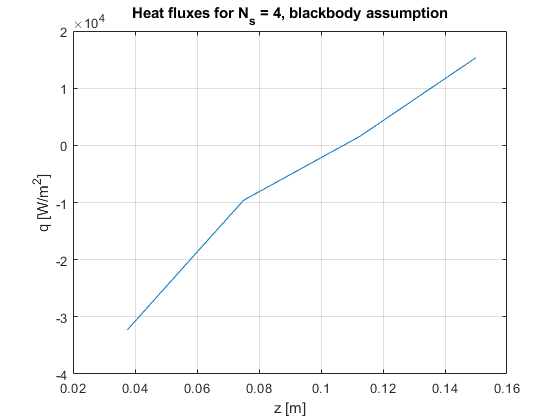

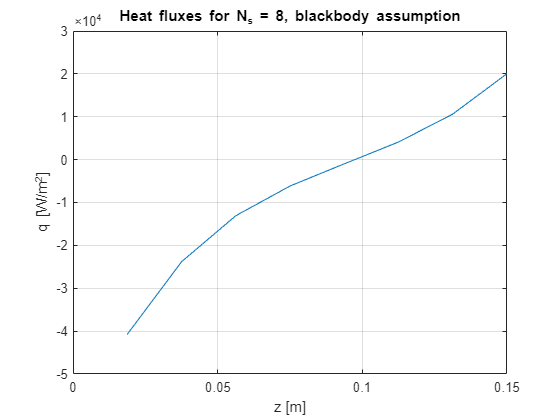

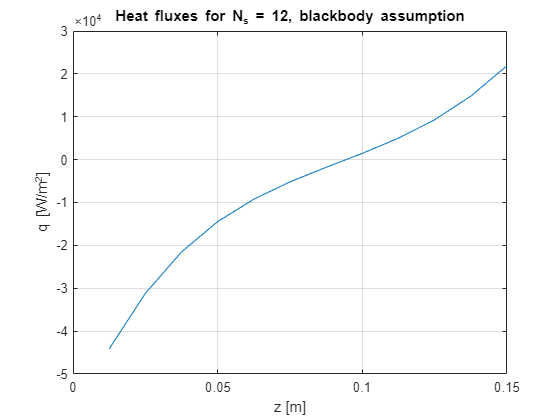

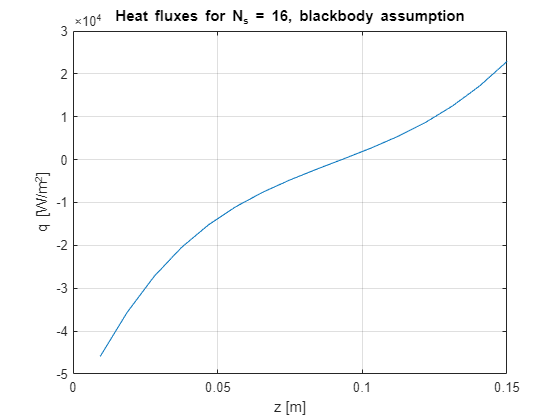

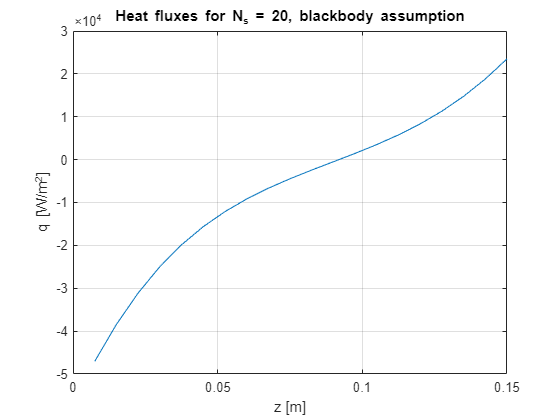

%Plot 1, Ns = 4
for n = 2:length(Ns)

    figure
    z = h/Ns(n)*.5*(1:(Ns(n)));
    plot(z, q_bb{n}(3:end))
    xlabel('z [m]')
    ylabel('q [W/m^2]')
    title(['Heat fluxes for N_s = ', num2str(Ns(n)), ', blackbody assumption'])
    grid on
end

### Gray-diffuse Surfaces

The heat fluxes for the gray-diffuse assumption are given by:


$$[q] ~=~[A]^{-1}[B][E_b]$$


Where:


$$A_{kj} ~=~   \frac{\delta_{kj}}{\epsilon_j} - F_{k-j}\left(   \frac{1 - \epsilon_j}{\epsilon_j}   \right)      $$


and:


$$B_{kj} ~=~ \delta_{kj} - F_{k-j}$$



for n = 1:length(Ns) %For each Ns value, compute all the blackbody heat fluxes and fill the relevant cell array elements
    
    N = Ns(n) + 2;
    T = [T1; T2; Ts*ones(Ns(n),1)]; %Vector of temperatures of each of the surfaces
    
    A_mat = zeros(N);
    B_mat = A_mat;
    for k = 1:N
        for l = 1:N
            %Kronecker Delta implemented here
            if k == l 

                A_mat(k,l) = 1/eps - F{n}(k,l)*(1 - eps)/eps; %Compute the coefficient matrix for the heat fluxes
                B_mat(k,l) = 1 - F{n}(k,l); %Compute the coefficient matrix for the blackbody hemispherical-total emissivities
            else 
                
                A_mat(k,l) = - F{n}(k,l)*(1 - eps)/eps; %Compute the coefficient matrix for the heat fluxes
                B_mat(k,l) = - F{n}(k,l); %Compute the coefficient matrix for the blackbody hemispherical-total emissivities                

            end

   
        end
    end
    
    q_gd{n} = A_mat\B_mat*sigma*T.^4; %Compute the heat fluxes for this value of N_s

end 


Plot the gray-diffuse results

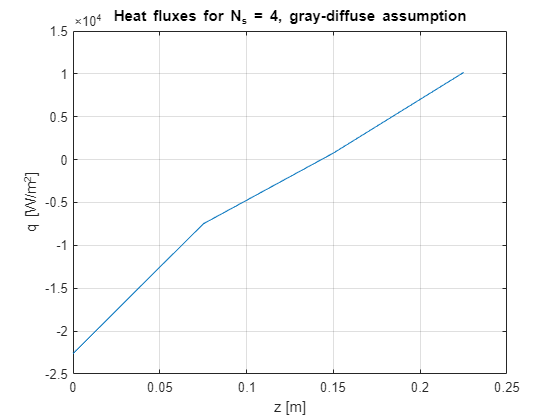

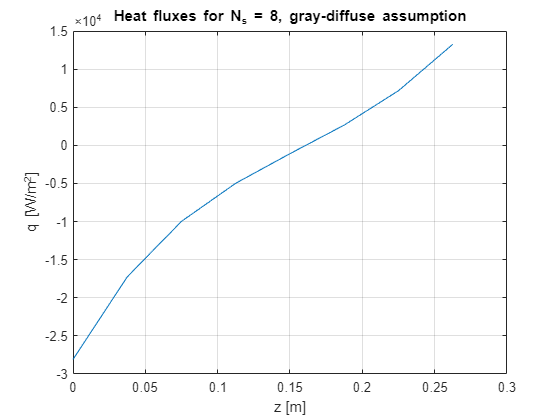

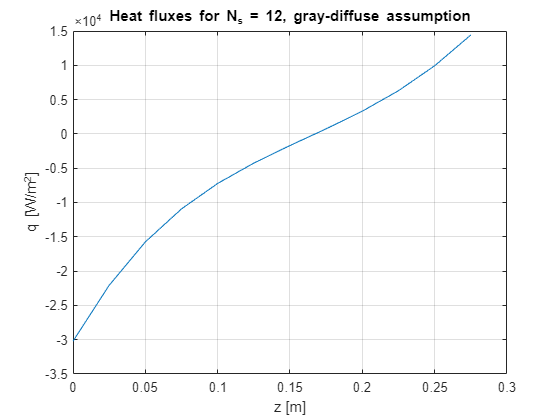

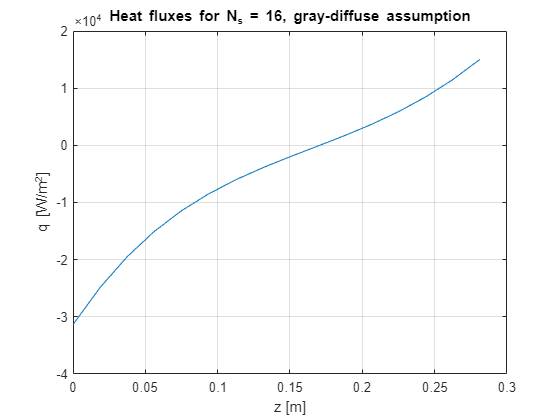

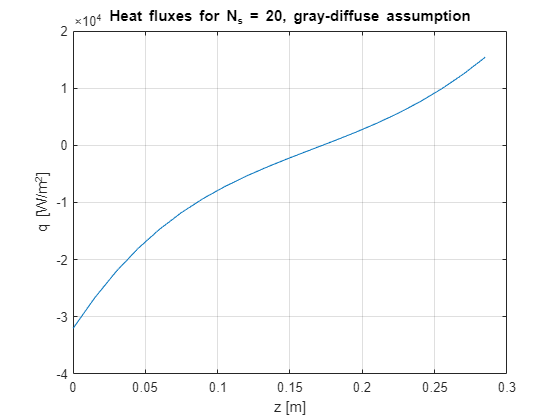

%Plot 1, Ns = 4
for n = 2:length(Ns)

    figure
    z = h/Ns(n)*(0:(Ns(n)-1));
    plot(z, q_gd{n}(3:end))
    xlabel('z [m]')
    ylabel('q [W/m^2]')
    title(['Heat fluxes for N_s = ', num2str(Ns(n)), ', gray-diffuse assumption'])
    grid on
end

## Discussion

As $N_s$ increases, the resolution of the curve of q vs z increases and it appears smoother. The heat flux estimate also decreases as $N_s$ increases. The shift in z that is visible is due to the fact that I have located the area elements at their bottom edge, for instance, $A_1$

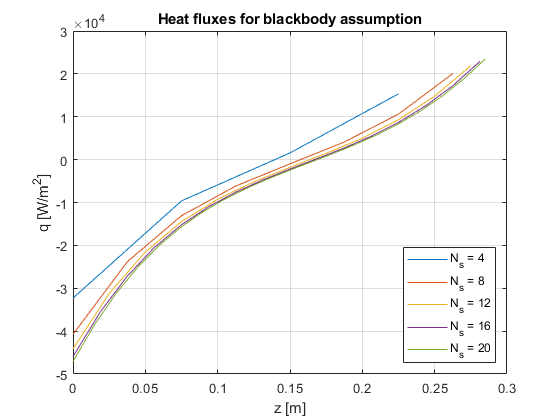

figure
    z2 = h/Ns(2)*(0:(Ns(2)-1));
    z3 = h/Ns(3)*(0:(Ns(3)-1));
    z4 = h/Ns(4)*(0:(Ns(4)-1));
    z5 = h/Ns(5)*(0:(Ns(5)-1));
    z6 = h/Ns(6)*(0:(Ns(6)-1));
    plot(z2, q_bb{2}(3:end),z3, q_bb{3}(3:end), z4, q_bb{4}(3:end), z5, q_bb{5}(3:end), z6, q_bb{6}(3:end))
    xlabel('z [m]')
    ylabel('q [W/m^2]')
    title('Heat fluxes for blackbody assumption')
    grid on
    legend('N_s = 4', 'N_s = 8', 'N_s = 12','N_s = 16', 'N_s = 20', 'Location', 'southeast')

For the gray-diffuse surfaces with emissivity 0.8, the magnitude of the heat fluxes required to maintain the prescribed temperatures are less than those of the black-body surfaces. The curve is steaper everywhere for the blackbody case and the extremes at the bottom and top surfaces are greater. 

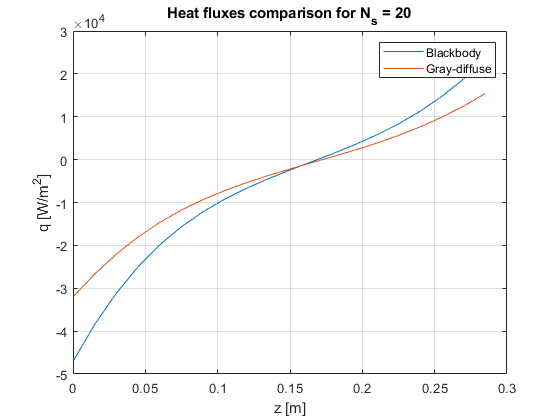

    figure
    z = h/Ns(end)*(0:(Ns(end)-1));
    plot(z, q_bb{end}(3:end),z, q_gd{end}(3:end) )
    xlabel('z [m]')
    ylabel('q [W/m^2]')
    title(['Heat fluxes comparison for N_s = ', num2str(Ns(n))])
    legend('Blackbody', 'Gray-diffuse')
    grid on